# Cell Growth exercise

### The overall goal of this exercise it to determine the cell growth rate (doubling rate) of a bacteria growth data set

There for we need to 

- import the data

- find a fit function

- use a fitting routine

- plot and check the data

First step: Clear your workspace, command window and close all plots:

close all
clear all
clc 

Task: Import the data  of DAXOpening.csv; name the arrays the same way as in the .csv file.

data = readtable('cellGrowth.csv');
time = table2array(data(:,1));
counts = table2array(data(:,2)); % counted cells

Now plot the data:

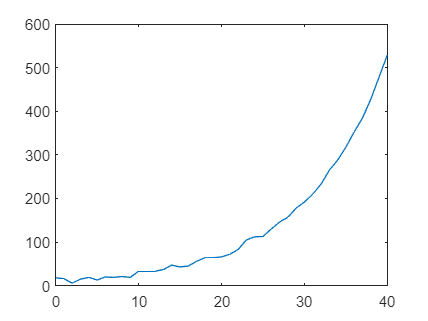

plot(time, counts)

Since the data is set, we can now take a look at the correct fitting function. You can think of the function by your self or you can scroll all the way down to the end of the script.

fun = @(x,time) x(1).*(2).^(time/x(2)); % function for fitting
fun2 = @(x,time) x(1).*(x(2)).^(time); % alternative function, but needs some addional calculations for doubling rate 

Now you need to think of some initial values. (if you have no idea, then just start with ones).

Use the lsqcurvefit() function to find the value.

x0 = [1,1]; % initial values
x = lsqcurvefit(fun,x0,time,counts);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x2 = lsqcurvefit(fun2,x0,time,counts);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Finally plot the data and the fit, to see if the fit was good. To make it a little prettier, add some labels() etc.

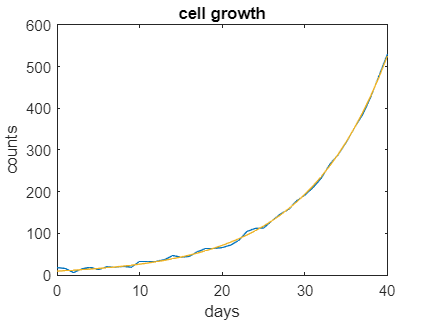

plot(time, counts, '.')
hold on
plot(time, fun(x, time))
plot(time, fun2(x2, time))
title('cell growth')
xlabel('days')
ylabel('counts')

function: a*2^(t/c) with t = time